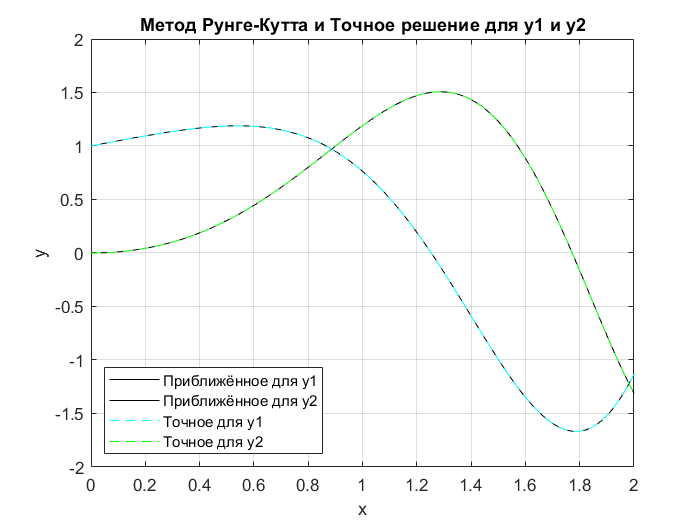

clear
clc
close all
u0_1 = 1;
u0_2 = 0;
h = 0.01;
a = 0;
b = 2;
n = (b-a)/h;
N = n+1;
x = a:h:b;

y1 = zeros(1, N);
y2 = zeros(1, N);

y1(1) = u0_1;
y2(1) = u0_2;


Y = [y1; y2];
Func = @(t, Y) [Y(1)/(2+2*t)-2*t*Y(2); Y(2)/(2+2*t)+2*t*Y(1)];

for i = 1:n
    K1 = Func(x(i), Y(:, i));
    K2 = Func(x(i)+h, Y(:, i)+h*K1);
    Y(:, i+1) = Y(:, i) + h*(0.5*K1+0.5*K2);
end


y1_ex = cos(x.*x).*sqrt(1+x);
y2_ex = sin(x.*x).*sqrt(1+x);



plot(x, Y(1, :), 'k',x, Y(2, :), 'k', x, y1_ex, '--c', x, y2_ex, '--g')
legend('Приближённое для y1', 'Приближённое для y2', 'Точное для y1', 'Точное для y2', 'Location','southwest')
grid on
title('Метод Рунге-Кутта и Точное решение для y1 и y2')
xlabel('x')
ylabel('y')

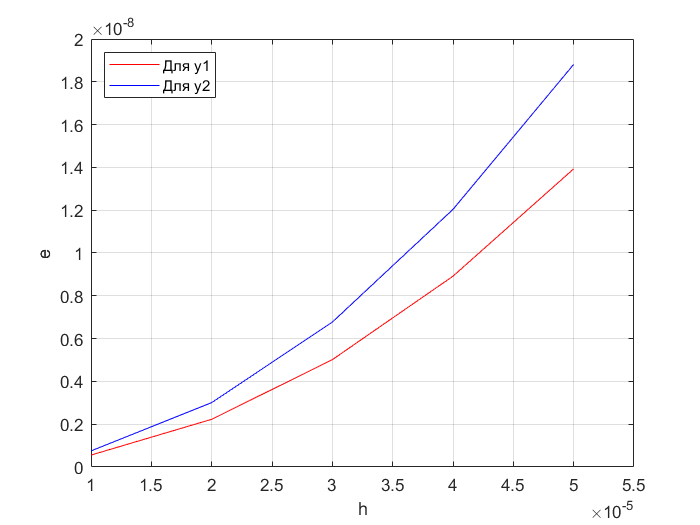


h_vec = 0.00001:0.00001:0.00005;
e1 = zeros(1, length(h_vec));
e2 = zeros(1, length(h_vec));

for i = 1:length(h_vec)
    x = a:h_vec(i):b;
    y1_ex = cos(x.*x).*sqrt(1+x);
    y2_ex = sin(x.*x).*sqrt(1+x);
    Y = zeros(2, length(x));
    Y(1,1) = y1_ex(1);
    Y(2,1) = y2_ex(1);
    for j = 1:length(x)-1
        K1 = Func(x(j), Y(:, j));
        K2 = Func(x(j)+h_vec(i), Y(:, j)+h_vec(i)*K1);
        Y(:, j+1) = Y(:, j) + h_vec(i)*(0.5*K1+0.5*K2);
    end
    e1(i) = (norm(y1_ex - Y(1, :),"inf"));
    e2(i) = (norm(y2_ex - Y(2, :),"inf"));
end


plot(h_vec, e1, 'r', h_vec, e2,'b')
xlabel("h")
ylabel("e") 
grid on
legend('Для y1', 'Для y2', 'Location','northwest')

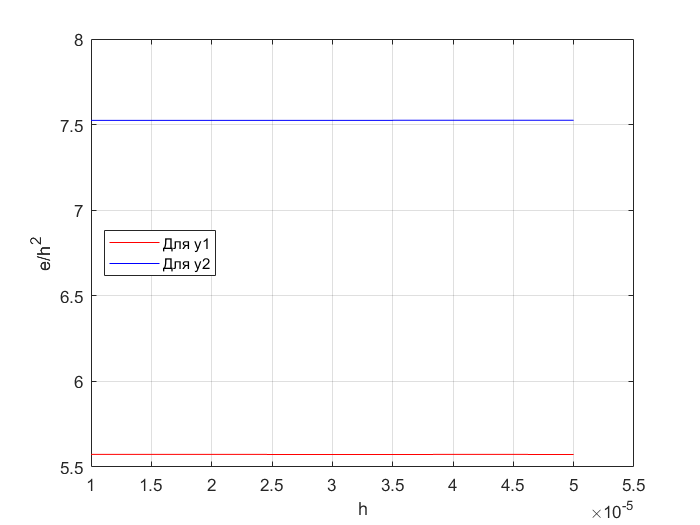



plot(h_vec, e1./h_vec.^2, 'r', h_vec, e2./h_vec.^2, 'b')
xlabel("h")
ylabel("e/h^2") 
legend('Для y1', 'Для y2', 'Location','west')
grid on

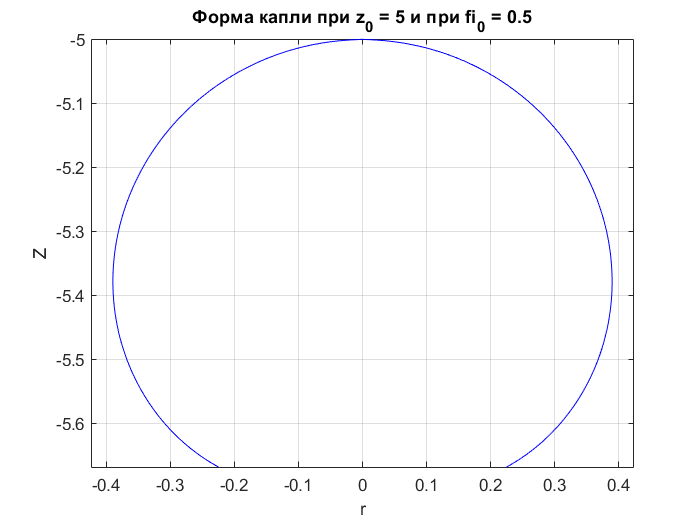



a = 0.39;
z0 = 5;
fi0 = 0.5;
fi(1) = fi0;
r(1) = 0;
Z(1) = -z0;
h = 0.001;
s(1) = 0;
i=1;
Y = [fi; r; Z];
K1 = [0, 0, 0];
K2 = [0, 0, 0];
while Y(1, i) <= pi - fi0
    K1 = F(s(i), Y(:, i), z0, a);
    K2 = F(s(i)+h, Y(:, i)+h*K1, z0, a);
    Y(:, i+1) = Y(:, i) + h*(0.5*K1+0.5*K2);
    s(i+1) = s(i)+h;
    i = i+1;
end


plot(-Y(2, :), Y(3, :), 'b', Y(2, :), Y(3, :), 'b')
xlabel("r")
ylabel("Z")
grid on
title(['Форма капли при z_0 = ', num2str(z0), ' и при fi_0 = ', num2str(fi0)])
axis equal

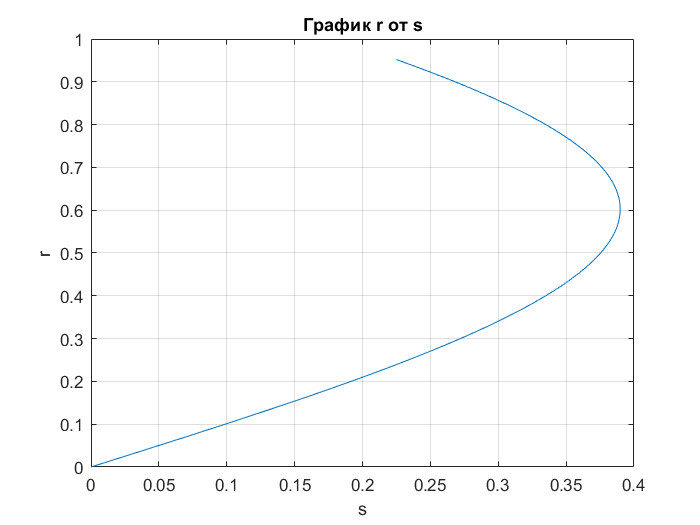

plot(Y(2, :), s)
xlabel("s")
ylabel("r")
grid on
title('График r от s')

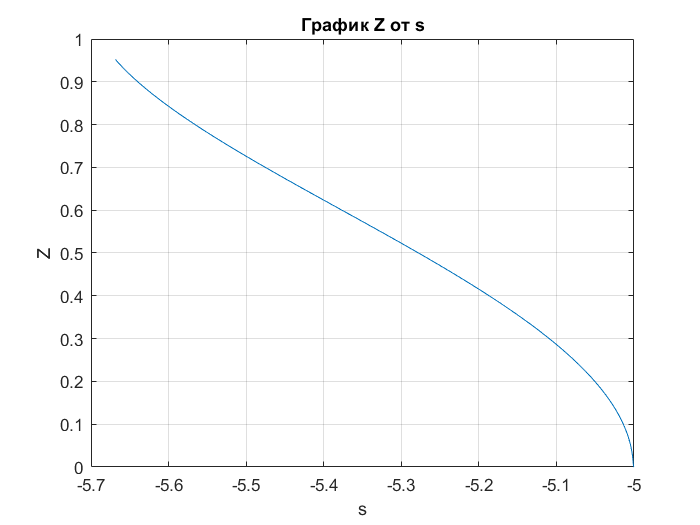


plot(Y(3, :), s)
xlabel("s")
ylabel("Z")
grid on
title('График Z от s')

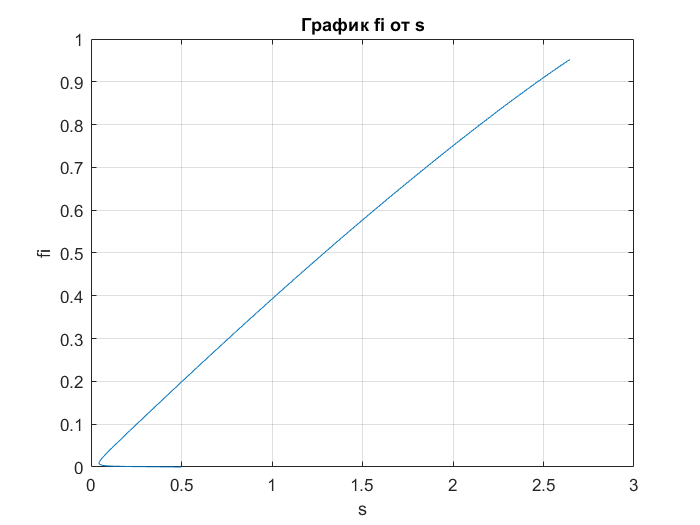


plot(Y(1, :), s)
xlabel("s")
ylabel("fi")
grid on
title('График fi от s')

function X = F(s, Y, z0, a)
    if s == 0
        X = [(-z0/(2*a*a)-Y(3)/a*a); cos(Y(1)); -sin(Y(1))];
    else
        X = [(-(sin(Y(1))/Y(2))-Y(3)/a*a); cos(Y(1)); -sin(Y(1))];
    end
end


